# Examples for using the `least_squares_fit` function.

Copyright © 2021 Tamas Kis

## Example #1: Linear fit.

Input the data (example data from [https://www.mathsisfun.com/data/least-squares-regression.html](https://www.mathsisfun.com/data/least-squares-regression.html)).

x = [2,3,5,7,9];
y = [4,5,7,10,15];

Obtain the coefficient vector $\mathbf{c}={\left(m,b\right)}^T$ for the linear fit, the coefficient of determination $r^2$, and the string storing the full equation.

[c,r2,eqn] = least_squares_fit(x,y);

 Extract the coefficients $m$ and $b$ (from $\mathbf{c}$) corresponding to the linear fit $y=\textrm{mx}+b$.

m = c(1);
b = c(2);

Initialize the domain and evaluate the linear fit over that domain.

x_fit = min(x):((max(x)-min(x))/1000):max(x);
y_fit = m*x_fit+b;

Produce a plot of the original data together with the linear fit.

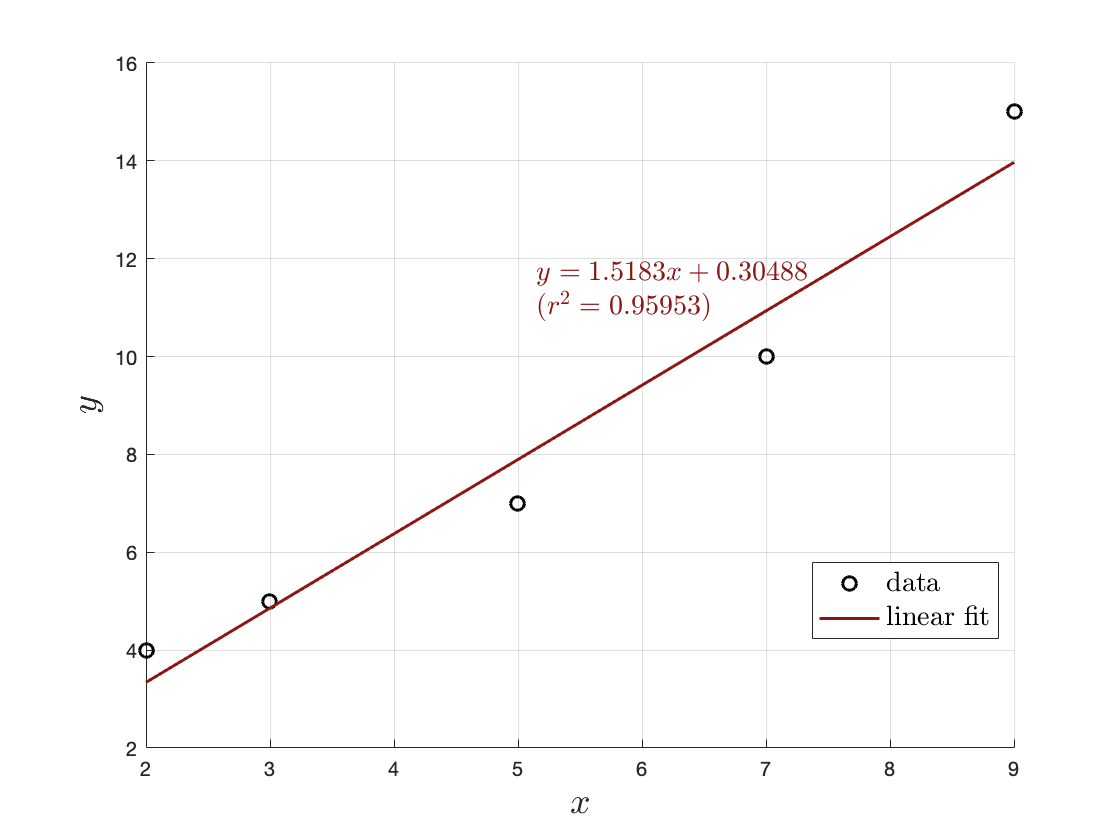

% initialize figure
figure;
hold on;

% plot data and fit
hold on;
plot(x,y,'ko','markersize',7,'linewidth',1.5);
plot(x_fit,y_fit,'color',[0.5490,0.0824,0.0824],'linewidth',1.5);
hold off;

% format plot and add labels/legend
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);
legend('data','linear fit','interpreter','latex','fontsize',14,...
    'location','best');

% label fit with equation + coefficient of determination
label_index = 3*round(length(x_fit)/4);
x_label = x_fit(label_index)-0.3*(max(x_fit)-min(x_fit));
y_label = y_fit(label_index);
text(x_label,y_label,[eqn,"$(r^{2}="+r2+")$"],'interpreter','latex',...
    'fontsize',14,'color',[0.5490,0.0824,0.0824]);

## Example #2: Polynomial (quadratic) fit.

Input the data (example data from [https://mste.illinois.edu/malcz/ExpFit/FIRST.html](https://mste.illinois.edu/malcz/ExpFit/FIRST.html)).

x = 0:1:16;
y = [8.3,11,14.7,19.7,26.7,35.2,44.4,55.9,68.9,83.2,98.8,114.2,127.1,...
    140.1,164,190.9,214.3];

Obtain the coefficient vector $\mathbf{c}={\left(c_0 ,c_1 ,c_2 \right)}^T$ for the quadratic fit, the coefficient of determination $r^2$, and the string storing the full equation.

[c,r2,eqn] = least_squares_fit(x,y,'poly',2);

Extract the coefficients $c_0$, $c_1$, and $c_2$ (from $\mathbf{c}$) corresponding to the quadratic fit $y=c_0 +c_1 x+c_2 x^2$.

c0 = c(1);
c1 = c(2);
c2 = c(3);

Initialize the domain and evaluate the quadratic fit over that domain.

x_fit = min(x):((max(x)-min(x))/1000):max(x);
y_fit = c0+c1*x_fit+c2*x_fit.^2;

Produce a plot of the original data together with the quadratic fit.

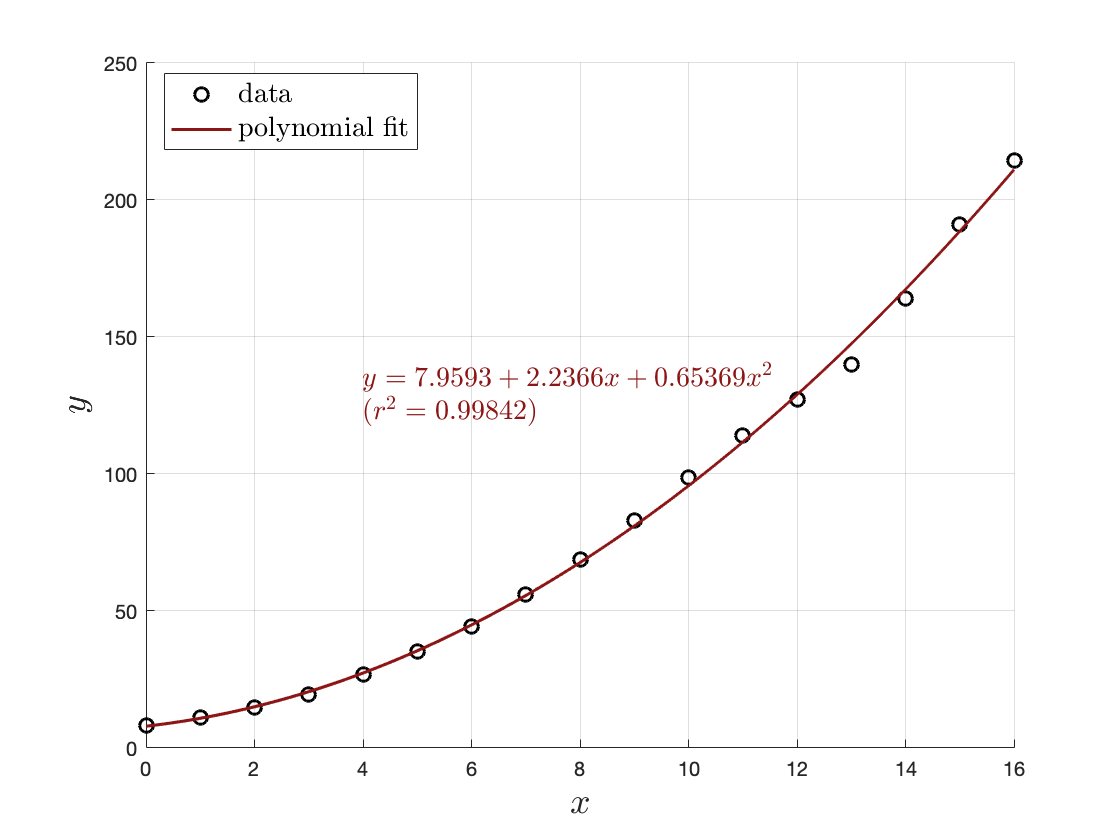

% initialize figure
figure;

% plot data and fit
hold on;
plot(x,y,'ko','markersize',7,'linewidth',1.5);
plot(x_fit,y_fit,'color',[0.5490,0.0824,0.0824],'linewidth',1.5);
hold off;

% format plot and add labels/legend
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);
legend('data','polynomial fit','interpreter','latex','fontsize',14,...
    'location','best');

% label fit with equation + coefficient of determination
label_index = 3*round(length(x_fit)/4);
x_label = x_fit(label_index)-0.5*(max(x_fit)-min(x_fit));
y_label = y_fit(label_index);
text(x_label,y_label,[eqn,"$(r^{2}="+r2+")$"],'interpreter','latex',...
    'fontsize',14,'color',[0.5490,0.0824,0.0824]);

## Example #3: Power fit.

Input the data (example data from [https://www.mathworks.com/matlabcentral/answers/65624-curve-fitting-a-power-function](https://www.mathworks.com/matlabcentral/answers/65624-curve-fitting-a-power-function)).

x = [0.5,2.4,3.2,4.9,6.5,7.8];
y = [0.8,9.3,37.9,68.2,155,198];

Obtain the coefficient vector $\mathbf{c}={\left(a,b\right)}^T$ for the power fit, the coefficient of determination $r^2$, and the string storing the full equation.

[c,r2,eqn] = least_squares_fit(x,y,'power');

 Extract the coefficients $a$ and $b$ (from $\mathbf{c}$) corresponding to the power fit $y={\textrm{ax}}^{b\;}$.

a = c(1);
b = c(2);

Initialize the domain and evaluate the power fit over that domain.

x_fit = min(x):((max(x)-min(x))/1000):max(x);
y_fit = a*x_fit.^b;

Produce a plot of the original data together with the power fit.

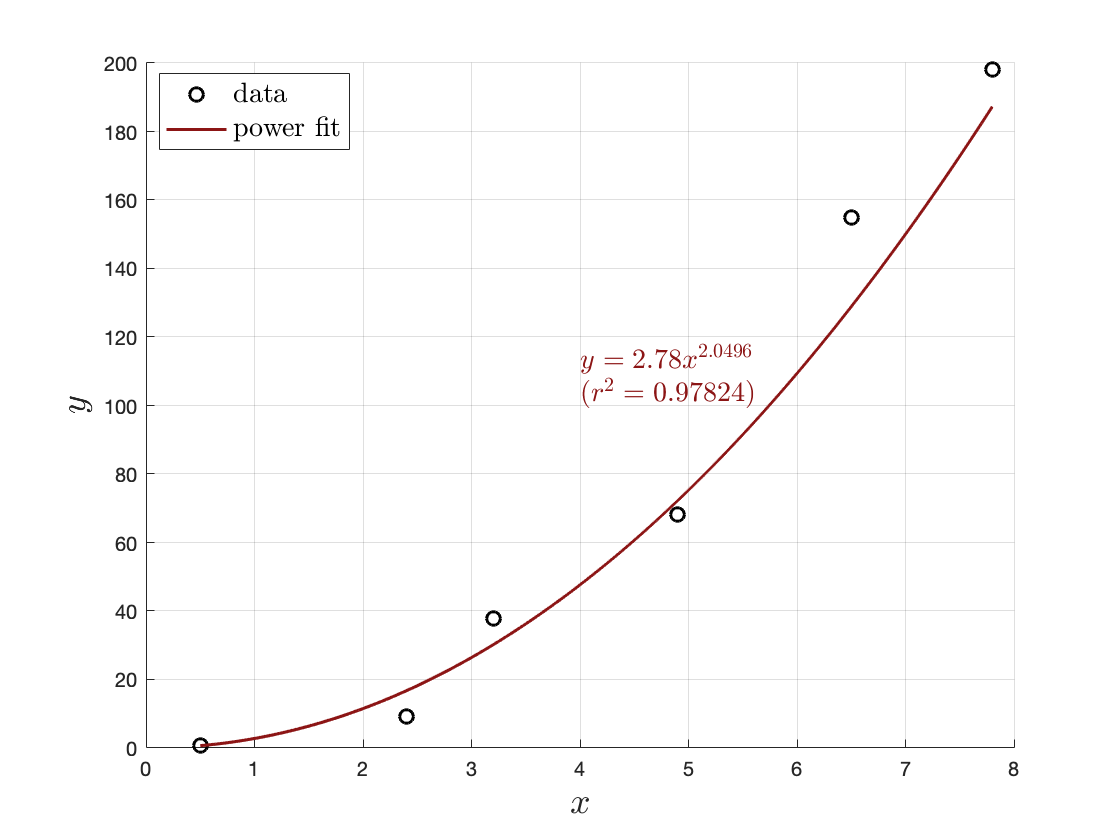

% initialize figure
figure;

% plot data and fit
hold on;
plot(x,y,'ko','markersize',7,'linewidth',1.5);
plot(x_fit,y_fit,'color',[0.5490,0.0824,0.0824],'linewidth',1.5);
hold off;

% format plot and add labels/legend
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);
legend('data','power fit','interpreter','latex','fontsize',14,...
    'location','best');

% label fit with equation + coefficient of determination
label_index = 3*round(length(x_fit)/4);
x_label = x_fit(label_index)-0.27*(max(x_fit)-min(x_fit));
y_label = y_fit(label_index);
text(x_label,y_label,[eqn,"$(r^{2}="+r2+")$"],'interpreter','latex',...
    'fontsize',14,'color',[0.5490,0.0824,0.0824]);

## Example #4: Exponential fit.

Input the data (example data from [https://mste.illinois.edu/malcz/ExpFit/FIRST.html](https://mste.illinois.edu/malcz/ExpFit/FIRST.html)).

x = 0:1:16;
y = [8.3,11,14.7,19.7,26.7,35.2,44.4,55.9,68.9,83.2,98.8,114.2,127.1,...
    140.1,164,190.9,214.3];

Obtain the coefficient vector $\mathbf{c}={\left(a,b\right)}^T$ for the exponential fit, the coefficient of determination $r^2$, and the string storing the full equation.

[c,r2,eqn] = least_squares_fit(x,y,'exp');

 Extract the coefficients $a$ and $b$ (from $\mathbf{c}$) corresponding to the exponential fit $y={\textrm{ae}}^{\textrm{bx}}$.

a = c(1);
b = c(2);

Initialize the domain and evaluate the exponential fit over that domain.

x_fit = min(x):((max(x)-min(x))/1000):max(x);
y_fit = a*exp(b*x_fit);

Produce a plot of the original data together with the exponential fit.

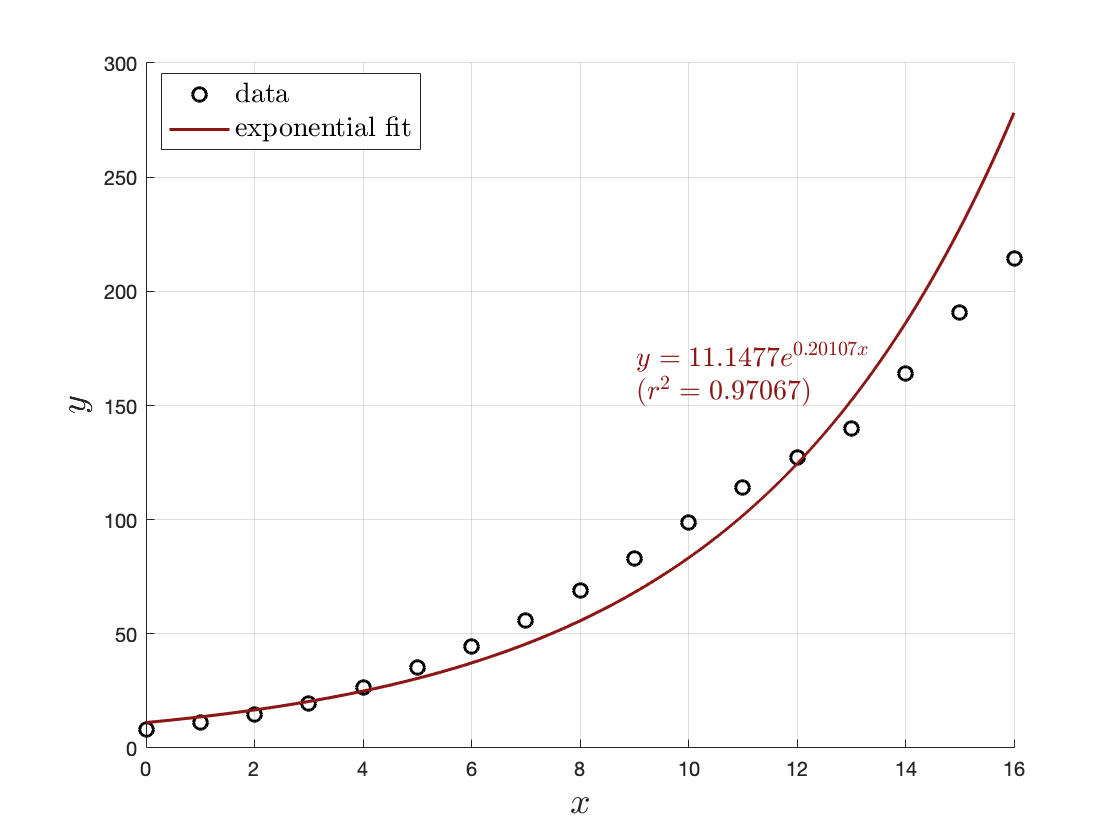

% initialize figure
figure;

% plot data and fit
hold on;
plot(x,y,'ko','markersize',7,'linewidth',1.5);
plot(x_fit,y_fit,'color',[0.5490,0.0824,0.0824],'linewidth',1.5);
hold off;

% format plot and add labels/legend
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);
legend('data','exponential fit','interpreter','latex','fontsize',14,...
    'location','best');

% label fit with equation + coefficient of determination
label_index = 5*round(length(x_fit)/6);
x_label = x_fit(label_index)-0.27*(max(x_fit)-min(x_fit));
y_label = y_fit(label_index);
text(x_label,y_label,[eqn,"$(r^{2}="+r2+")$"],'interpreter','latex',...
    'fontsize',14,'color',[0.5490,0.0824,0.0824]);

## Example #5: Logarithmic fit.

Input the data (example data from [https://stackoverflow.com/questions/3433486/how-to-do-exponential-and-logarithmic-curve-fitting-in-python-i-found-only-poly](https://stackoverflow.com/questions/3433486/how-to-do-exponential-and-logarithmic-curve-fitting-in-python-i-found-only-poly)).

x = [1,7,20,50,79];
y = [10,19,30,35,51];

Obtain the coefficient vector $\mathbf{c}={\left(a,b\right)}^T$ for the logarithmic fit, the coefficient of determination $r^2$, and the string storing the full equation.

[c,r2,eqn] = least_squares_fit(x,y,'log');

 Extract the coefficients $a$ and $b$ (from $\mathbf{c}$) corresponding to the logarithmic fit $y=a+b\;\ln \left(x\right)$.

a = c(1);
b = c(2);

Initialize the domain and evaluate the logarithmic fit over that domain.

x_fit = min(x):((max(x)-min(x))/1000):max(x);
y_fit = a+b*log(x_fit);

Produce a plot of the original data together with the logarithmic fit.

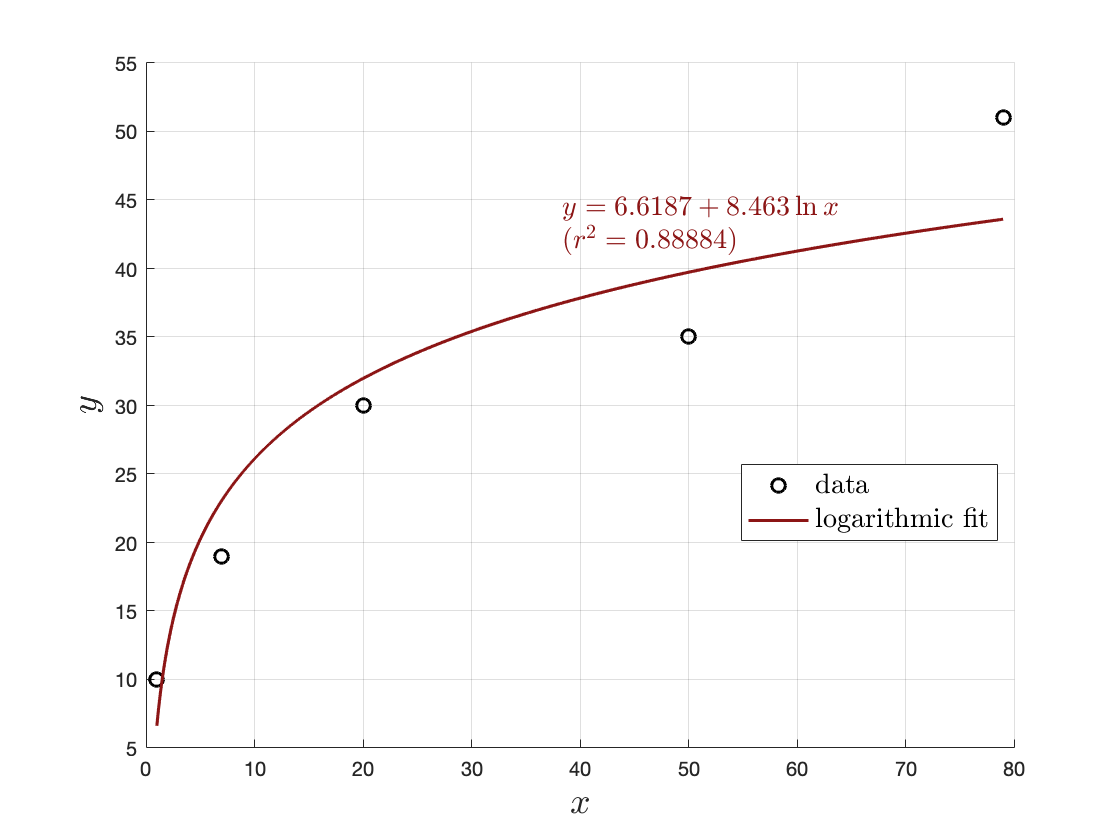

% initialize figure
figure;

% plot data and fit
hold on;
plot(x,y,'ko','markersize',7,'linewidth',1.5);
plot(x_fit,y_fit,'color',[0.5490,0.0824,0.0824],'linewidth',1.5);
hold off;

% format plot and add labels/legend
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);
legend('data','logarithmic fit','interpreter','latex','fontsize',14,...
    'location','best');

% label fit with equation + coefficient of determination
label_index = 3*round(length(x_fit)/4);
x_label = x_fit(label_index)-0.27*(max(x_fit)-min(x_fit));
y_label = y_fit(label_index)+0.05*(max(y_fit)-min(y_fit));
text(x_label,y_label,[eqn,"$(r^{2}="+r2+")$"],'interpreter','latex',...
    'fontsize',14,'color',[0.5490,0.0824,0.0824]);